# Mach band illusion

Mach带（Mach band）错觉是一种经典的视觉感知现象。在一组亮度渐变的灰条交界处，人眼会看到边缘附近的区域比实际亮度更亮或更暗。

具体来说，在亮-暗两条灰带的交汇线附近，亮的一侧看起来更亮，暗的一侧看起来更暗。

## Create the visual input for the Mach Band Illusion.

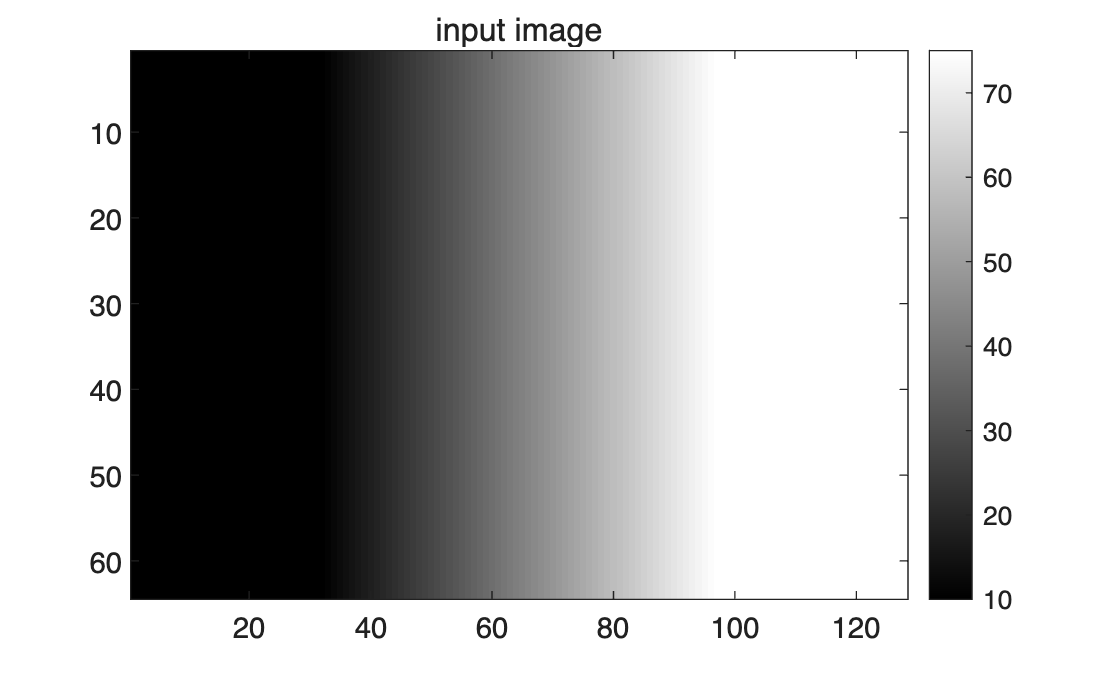

clear all; clc;

matrix = zeros(64, 128);
matrix(:, 1:32) = 10;
for i = 1:65
    matrix(:, 32+i) = 10+i;
end
matrix(find(matrix == 0)) = 75;

% plot figure
figure;
imagesc(matrix);
colormap('gray');
axis off;
title('input image');
colorbar;

### At the transition from the ramp to the white area, you should see a brighter vertical bar. At the transition from the ramp to the black area, you should see a darker vertical bar.

## Plot brightness as a function of horizontal position.

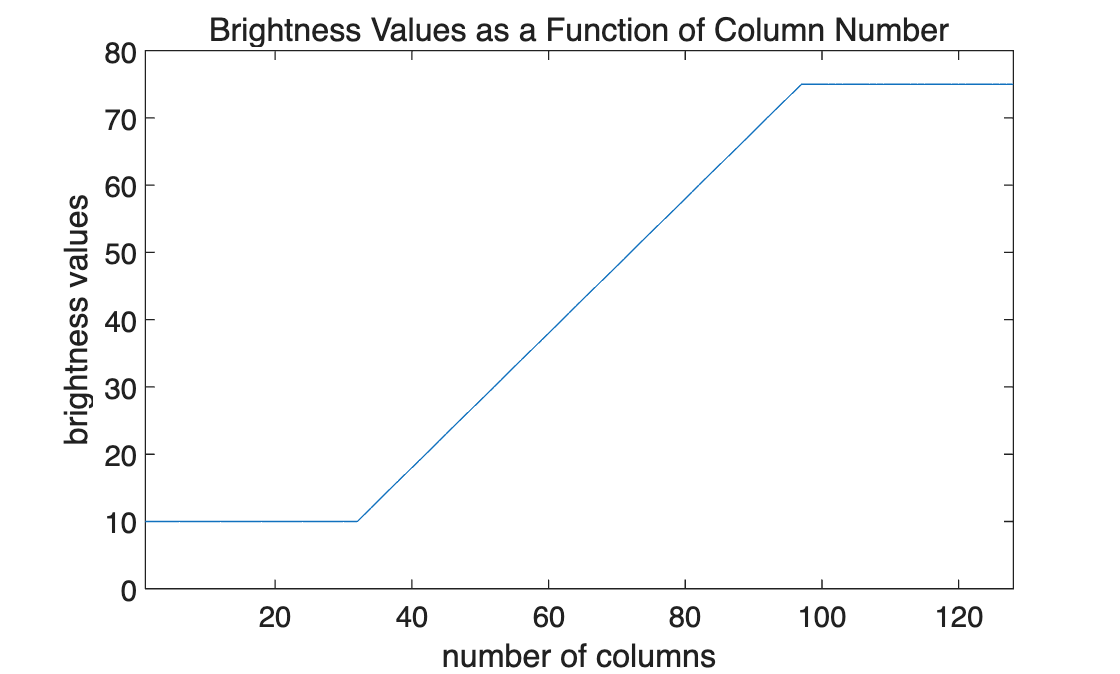

figure;
plot(matrix(1,:))
axis tight;
ylim([0 80]);
title('Brightness Values as a Function of Column Number');
xlabel('number of columns');
ylabel('brightness values');

### 这是视觉输入图的颜色（亮度）横向的变化趋势。颜色变化是平滑的。

## Create the receptive field of a retinal ganglion cell.

可以通过2D高斯差分来描述中心-周围拮抗感受野。

感受野中心部分用一个较窄、方差较小的二维高斯函数来建模。代表兴奋 (Excitatory) 区域。

感受野周围部分用一个较宽、方差较大的二维高斯函数来建模。代表抑制 (Inhibitory) 区域。

即

中心区域：$G_e \left(x,y\right)=\frac{1}{2\pi {\sigma_e }^2 }*e^{-\frac{1}{2{\sigma_e }^2 }\left(x^2 +y^2 \right)}$

周围区域：$G_i \left(x,y\right)=\frac{1}{2\pi {\sigma_i }^2 }*e^{-\frac{1}{2{\sigma_i }^2 }\left(x^2 +y^2 \right)}$

其中$\sigma_e <\sigma_i$

通过一定比例的加权，将二者做差描述完整的感受野：$\left.{\mathrm{RF}\left(x,y\right)=S*\left\lbrack G\right.}_e \left(x,y\right)-\mathrm{IE}*G_i \left(x,y\right)\right\rbrack$

其中S is the overall strength of the field’s connectivity; IE is the ratio of inhibition to excitation.

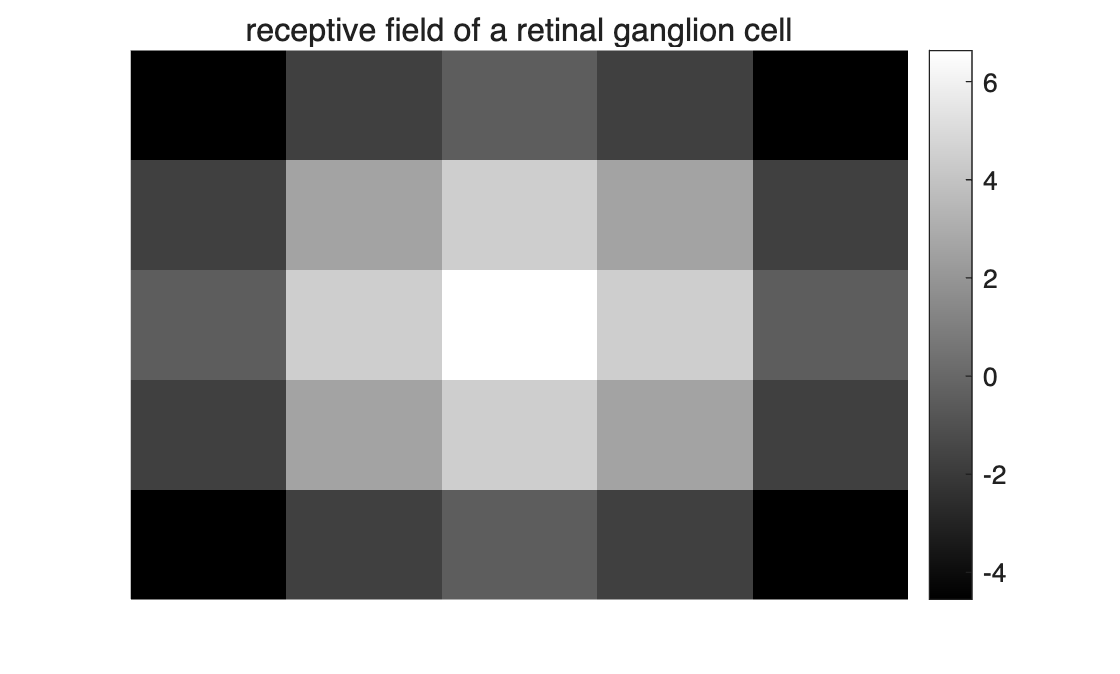

x = -2:1:2;
[X, Y] = meshgrid(x);
R = sqrt(X.^2 + Y.^2);
sigma_center = 2;
sigma_surround = 6;
Excitetory_center = 1/(2*pi*sigma_center^2) * (exp(-(R.^2)/(2*sigma_center^2)));
Inhibitory_surround = 1/(2*pi*sigma_surround^2) * (exp(-(R.^2) / (2*sigma_surround^2)));

%S*(Egaus – IE*Igaus) 
S = 500;    %the overall strength of the field's connectivity
IE = 6;     %the ratio of inhibition to excitation
receptive_field = S*(Excitetory_center - IE*Inhibitory_surround);

%plot figure
figure;
imagesc(receptive_field);
colormap('gray');
colorbar;
axis off;
title('receptive field of a retinal ganglion cell');

## Convolve your receptive field and input image.

通过卷积，计算视网膜上所有被激活的神经节细胞对输入图像初步处理加工的结果。

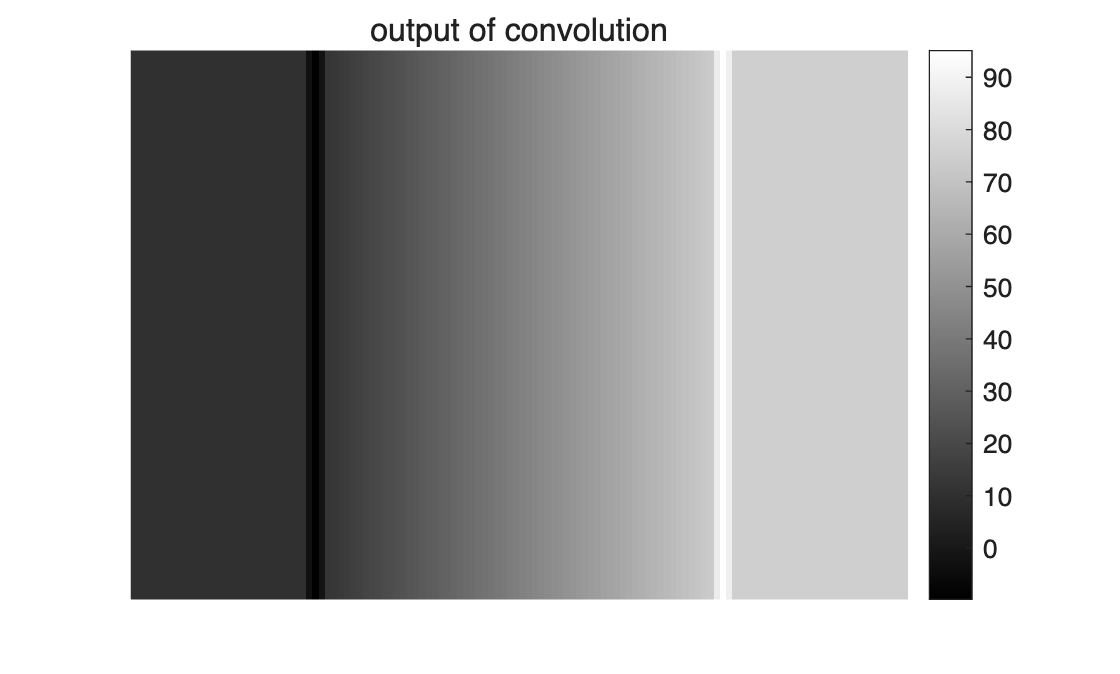

matrix_conv = conv2(matrix,receptive_field,'valid');

%plot figure
figure;
imagesc(matrix_conv);
colormap('gray');
colorbar;
axis off;
title('output of convolution');

### 这里可以看到在经过神经节细胞初步处理过后，输入图像出现了两个明显的条带

## Plot brightness as a function of horizontal position again.

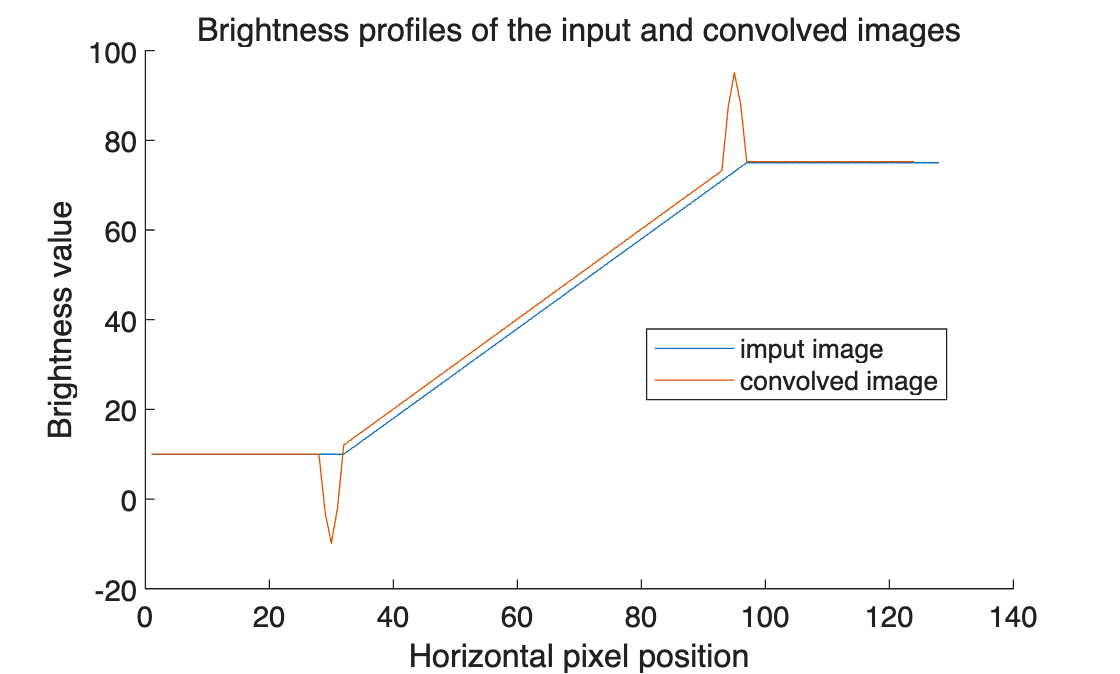

figure;
hold on;
plot(matrix(1,:));
plot(matrix_conv(1,:));
hold off;
xlabel('Horizontal pixel position');
ylabel('Brightness value');
title('Brightness profiles of the input and convolved images');
legend('imput image', 'convolved image','Location','best');

### 这里能够看到经过神经节细胞处理过后的图像在颜色变化交界处出现了颜色的突变。

## Conclusion

The Mach Band illusion in the plots arises from the enhanced contrast at luminance edges after convolving the input with a center-surround receptive field model. This illusion occurs at the retinal due to the antagonistic center-surround organization of receptive fields. It reveals a desirable property of the visual system—emphasizing edges to efficiently and robustly represent visual scenes.